Script for testing the IpDFT and eIpDFT function

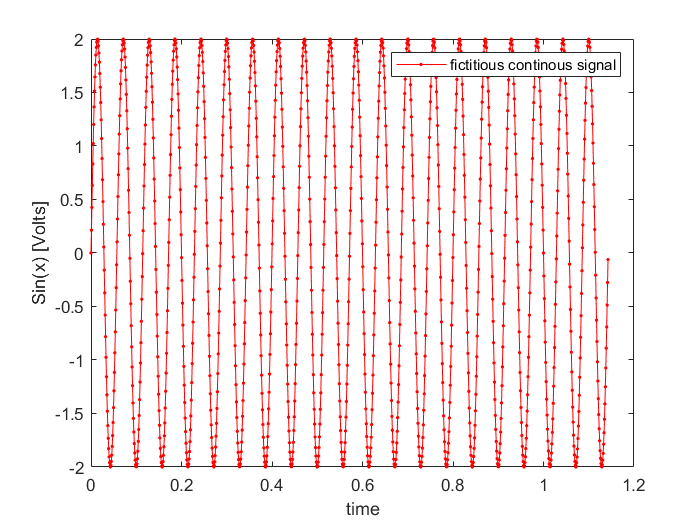

% Generate a test data
fs = 1024; % sample rate (Hz)
delta_t = 1/fs; % seconds per sample 
F = 17.5; % 16 Hz fundamental frequency 
T = 1/F; % Period 
t = 0:delta_t:20*T;
x = 2*pi*F*t;
freq = 0:fs/length(x):fs/2; % frequency in Hz
figure
fictitious_continous_signal = 2*sin(x);
plot(t, fictitious_continous_signal, 'color', 'r', 'Marker', '.')
xlabel('time')
ylabel('Sin(x) [Volts]')
legend('fictitious continous signal')

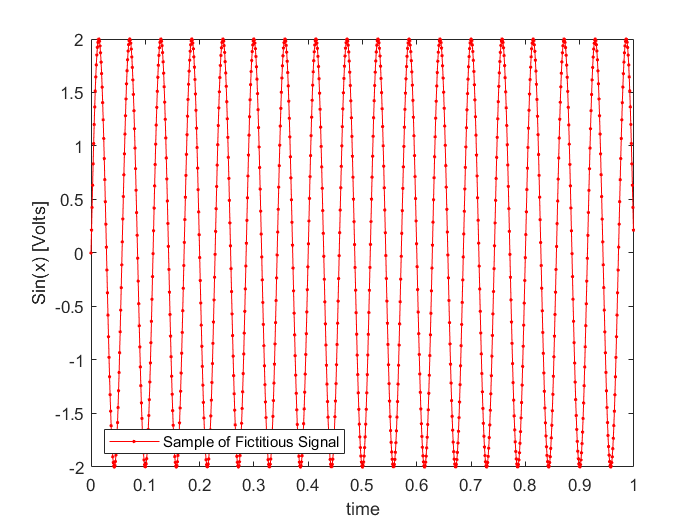

% Let's take a sample of this continous signal at random rectangular
% window
sample_end = (2^10);
sample_start = 1;

sample = fictitious_continous_signal(sample_start: sample_end);

figure
plot(t_test(sample_start:sample_end), sample, 'color','r', 'Marker',".")
xlabel('time')
ylabel('Sin(x) [Volts]')
legend('Sample of Fictitious Signal', 'Location', 'southwest')

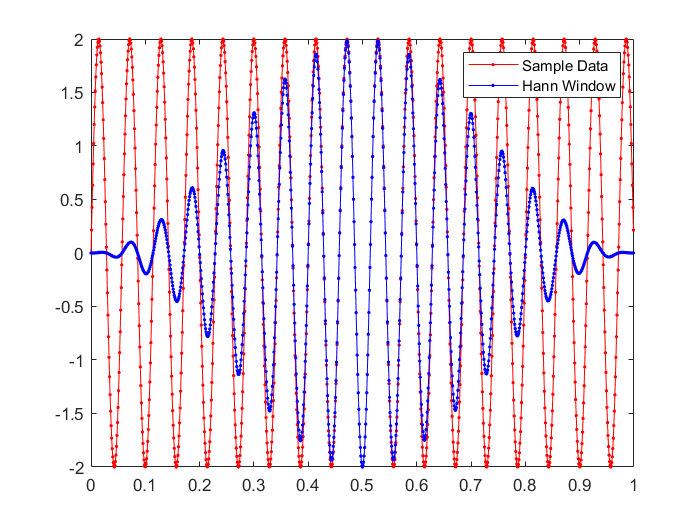

hann_window = hann(length(sample));
sample_hann_window = sample .* hann_window';
figure
% plot sample data with and without windowing
plot(t(sample_start:sample_end), sample, 'color','r', 'Marker',"."); hold on
plot(t(sample_start:sample_end), sample_hann_window, 'color','blue', 'Marker',"."); 
legend('Sample Data', 'Hann Window'); hold off

% Performing fft
DFT_sample = fft(sample_hann_window);
N = length(hann_window);
[f1, A1, ph1, delta1, eps1] = IpDFT(DFT_sample, N, -1, fs, '3p')

f1 = 17.5007

A1 = 511.4484

ph1 = -1.5713

delta1 = -0.4993

eps1 = -1

k = 0:(N-1);
[f, A, ph, delta, eps] = eIpDFT(DFT_sample, N, -1, fs, 20, f1, A1, ph1, k, '3p')

f = 17.4993

A = 511.4445

ph = -1.5703

delta = 0.4993

eps = 1